# **A kinetic Monte Carlo (kMC) Model for the Dynamics of Infectious Diseases**

## Why this project?

- Drawn into epidemiology by former graduate student ([Yashleen Sharma](https://yaesoubilab.ucsf.edu/team))

- Highlight opportunities in the field ([CDC](https://www.cdc.gov/stem/php/college-and-professional/see-yourself-in-a-public-health-career.html?CDC_AAref_Val=https://www.cdc.gov/stem/careers/index.html), [US Navy](https://www.med.navy.mil/Naval-Medical-Research-Command/R-D-Commands/Naval-Health-Research-Center/Core-Research/Operational-Infectious-Diseases/), etc..)

- [Introduction to Epidemiology](https://www.cdc.gov/training-publichealth101/php/training/introduction-to-epidemiology.html)

## Infection Dynamics: A Differential Equations Approach 

### I. SIR Model (Closed System)

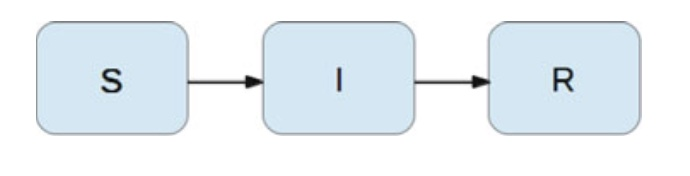

S: Susceptible population    I: Infected population    R: Recovered population

**Governing Equations**:

Let ${\bf u} = \pmatrix{S \cr I  \cr R}$, 


$$\frac{d\bf{u}}{dt} = \pmatrix{\frac{dS}{dt} \cr \frac{dI}{dt} \cr \frac{dR}{dt} } = \pmatrix{ -\beta SI \cr \beta SI - \gamma I \cr \gamma I} = f({\bf u})$$


- $\beta$ and $\gamma$ are given constants with units $\frac{1}{\mathrm{number} \cdot \mathrm{time}}$ and $\frac{1}{\mathrm{time}}$ respectively.

A particular numerical solution:

Initial condtions: $S_0 = 50, I_0 = 1, R_0 = 0$

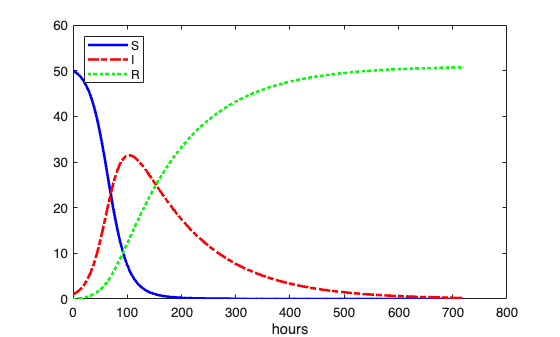

beta = 10/(40*8*24); % Over some 24 hour span, S(0) = 40, S(24) = 30, I(0)=8; i.e. delta S = -10
gamma = 3/(15*24);   % Over some 24 hour period, I(0) = 15, I(24) = 12, delta R = 3
dt = 1;                % Time unit: 1h 
D = 30;                % simulate infection dynamics over 30 days
N_t = floor(D*24/dt);  % number of discrete time steps
tspan = 0:1:N_t;
u0 = [50;1;0];         % initial condition

[t,u] = ode45(@(t,u) fSIR(t,u,beta,gamma),tspan,u0); % Solve the ODE using the ode45  on the time interval [0 D] with initial value u0

plot(t, u(:,1),'b-', t, u(:,2), 'r-.', t, u(:,3),'g:',LineWidth=2)
legend('S','I','R',Location='northwest');
xlabel('hours')

### II. SIRV Model (Closed System)

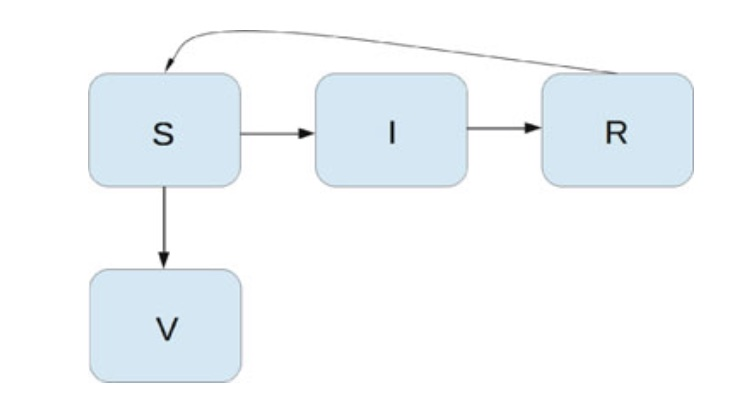

S: Susceptible    I: Infected    R: Recovered (time-restricted immunity)    V: vaccinated

Now ${\bf u} = \pmatrix{S \cr I \cr R  \cr V}$,


$$\frac{d\bf{u}}{dt} = \pmatrix{\frac{dS}{dt} \cr \frac{dI}{dt} \cr \frac{dR}{dt}  \cr \frac{dV}{dt} } = \pmatrix{ -\beta SI + \nu R - pS  \cr \beta SI - \gamma I \cr \gamma I - \nu R \cr pS} = f({\bf u})$$


- $\nu$ and $p$ are constants with unit: $\frac{1}{\mathrm{time}}$

A particular numerical solution:

Initial condtions: $S_0 = 50, I_0 = 1, R_0 = 0, V_0 = 0$

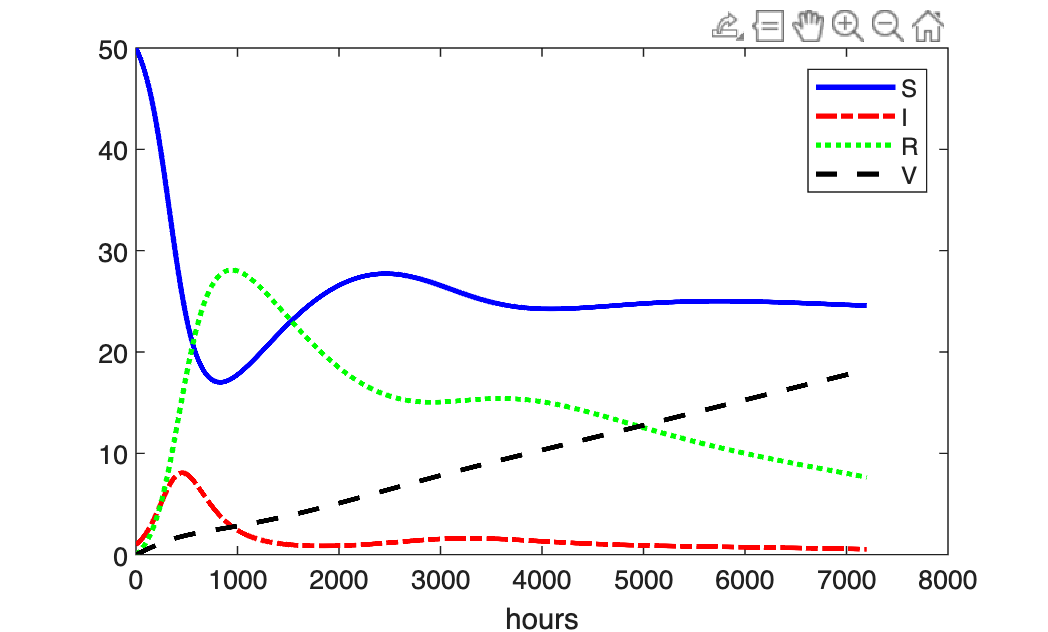

beta = 10/(40*8*24); 
beta = beta/4;
gamma = 3/(15*24);   
nu = 1/(24*50);      
p = 0.0001;

dt = 1;                % Time unit: 1h 
D = 300;                % simulate infection dynamics over 30 days
N_t = floor(D*24/dt);  % number of discrete time steps
tspan = 0:1:N_t;
u0 = [50;1;0;0];         % initial condition

[t,u] = ode45(@(t,u) fSIRV(t,u,beta,gamma,nu,p),tspan,u0); % Solve the ODE using the ode45  on the time interval [0 D] with initial value u0

plot(t, u(:,1),'b-', t, u(:,2), 'r-.', t, u(:,3),'g:',t,u(:,4),'k--',LineWidth=2)
legend('S','I','R','V',Location='northeast');
xlabel('hours')

## Infection Dynamics: Kinetic Monte Carlo (Agent Based) Approach

- Model the population as a set of interacting particles (agents)

- Each agent has specific characteristics (susceptible, infectious, recovered, vaccinated, age, social behavior, etc..)

- Probability of infection for agent $i$ is a function of the distance to infected individuals $j$ in an infection radius

Let $P_i:$Daily probability that person $i$ at position $(x_i, y_i)$ is infected


$$P_i = \sum_{j} P_{ij}$$


$P_{ij} = P_{ij}(r_{ij})$, $r_{ij} = \sqrt{(x_i - x_j)^2 + (y_i - y_j)^2}$: Proximity to infected people matters

Example: **Let's look at code**

### OUR GOAL: IMPLEMENT A KMC MODEL FOR THE DYNAMICS OF COVID-19

#### Some issues:

- How to speed up $O(N^2)$ interactions

- We need to average over hundreds (thousands) of runs. How will we achieve this?

- Data for comparison

#### Main references:

- De-Leon, H., Pederiva, F., Particle Modeling of the spreading of coronavirus disease (COVID-19), *Phys. Fluids*, 32, 087113, 2020

- De-Leon, H., Aran, D., MAM: Flexible Monte-Carlo Agent based model for modelling COVID-19 spread, J. Biomed. Inform., 141, 104364, 2023

### A Plan For The Next Three Days:

- Implement a KMC Model with vaccination

- Implement a cell list for particle interactions

- Implement reference 1 (COVID-19 with no vaccination)

- Abstract and implement reference 2 ("age structured", infectious disease dynamics with varying infection rates and  varying vaccine effectiveness)

[Comparison of transmission models for infectious diseases.](https://www.cdc.gov/cfa-modeling-and-forecasting/about/explainer-transmission-models.html)